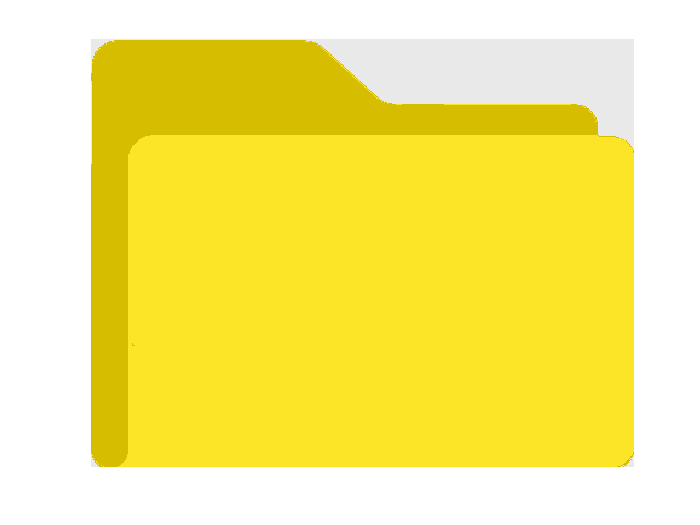

%{

     IconCreator live script for changing color content of tricolor png
     images

     May need to run a few times because color assignment from bins is
     random

%}

format short
format compact
close all
clear
clc

icon = 'load_bw.png'; % image name
filename = sprintf('%s\\%s', cd, icon);
colors = [...
     215, 189, 0; ... % background color
     252, 228, 38; ... % primary color
     233.121, 233.121, 233.121 ... % secondary color
     ];

img = double(imadjust(rgb2gray(imread(filename, 'png'))));

r_init = size(img, 1);
c_init = size(img, 2);

img = reshape(img, numel(img), []);
[bins, ~] = kmeans(img, 3, ...
     'Distance', 'cityblock', ...
     'Replicates', 5, ...
     'MaxIter', 1e3);

c1 = (bins == 1) .* colors(1, :);
c2 = (bins == 2) .* colors(2, :);
c3 = (bins == 3) .* colors(3, :);

temp_img = c1 + c2 + c3;
img = temp_img;

img = reshape(img, r_init, c_init, 3);

figure
imagesc(img/255)
box off
axis off

imwrite(img/255, sprintf('%s\\_%s', cd, icon));